clear all
clc
syms t
% pm_modulation
x(t)=sin(20*pi*t)

$$x(t) = \sin\left(20\,\pi \,t\right)$$

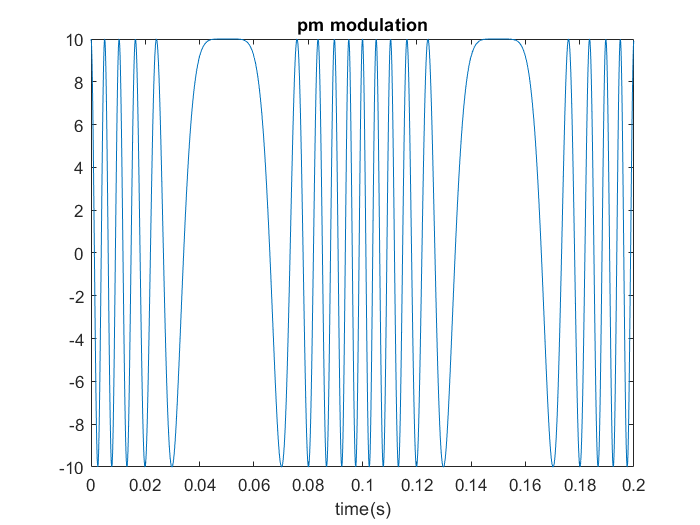

[xc_sample,t_sample]=pmm(x,10,100,10,10e03); 
figure(1)
plot(t_sample,xc_sample)
title('pm modulation')
xlabel('time(s)')


% narrow_band_pm

[xc_sample,t_sample]=nb(x,10,100,10,10e03); 

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-100\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

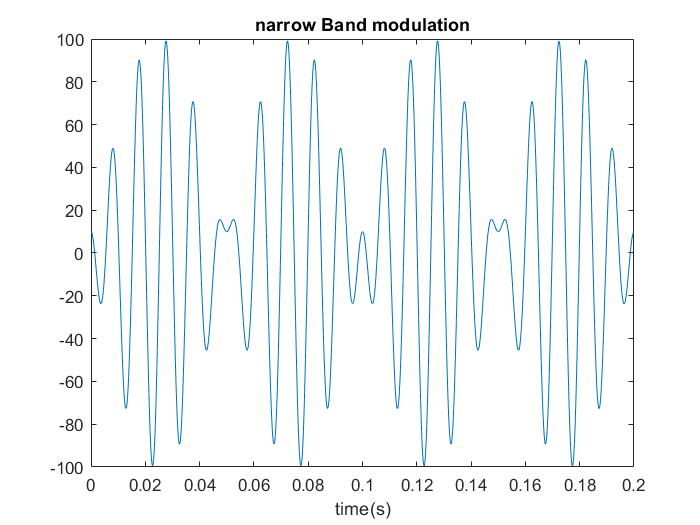

figure(2)
plot(t_sample,xc_sample)
title('narrow Band modulation')
xlabel('time(s)')


% finding max kp to have minimum error

n=0;
k=0;
for kp=-1:0.1:1 
    k=k+1
   [pm,~]=pmm(x,10,100,kp,10e03); 
   [narrow_band,~]=nb(x,10,100,kp,10e03);
   Error(k)=immse(narrow_band,pm);
   if abs(Error(k))<=0.01
    n=n+1;
    kp_array(n)=kp;   
   end
   
end

k = 1

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+10\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 2

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+9\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 3

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+8\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 4

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+7\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 5

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+6\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 6

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+5\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 7

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+4\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 8

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+3\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 9

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+2\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 10

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)+\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 11

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)$$

k = 12

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 13

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-2\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 14

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-3\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 15

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-4\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 16

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-5\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 17

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-6\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 18

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-7\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 19

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-8\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 20

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-9\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

k = 21

$$xnb(t) = 10\,\cos\left(200\,\pi \,t\right)-10\,\sin\left(20\,\pi \,t\right)\,\sin\left(200\,\pi \,t\right)$$

kp_max=max(kp_array)

kp_max = 0.2000

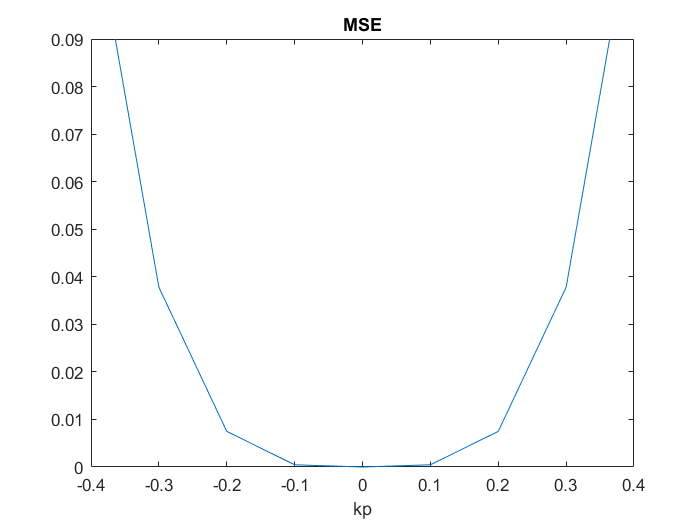

figure(3)
kp_baze=-1:0.1:1;
plot(kp_baze,Error,kp_baze,0.21)
ylim([0 0.09])
title('MSE')
xlabel('kp')

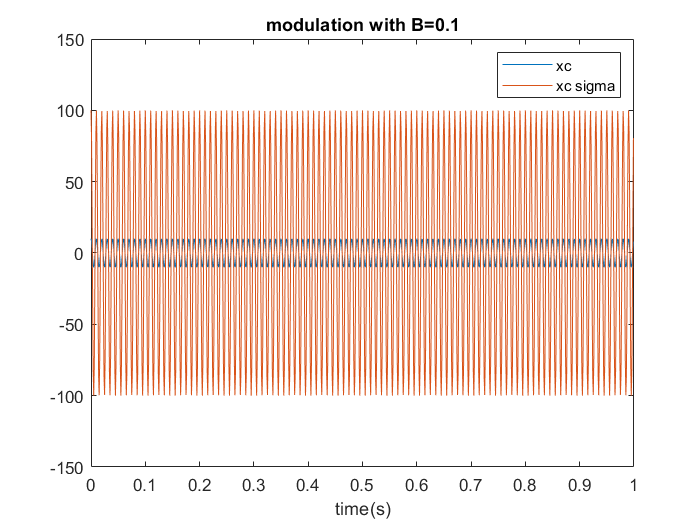

clear all
clc

fs=1000;
t=0:1/fs:1-1/fs;
f=fs/2*linspace(-1,1,fs);
[xc1,xc1_sum_series,XC1f,XC1_sum_f]=tone_modulation_func(10,100,0.1,10,2,fs);   %B=0.1
[xc2,xc2_sum_series,XC2f,XC2_sum_f]=tone_modulation_func(10,100,1,10,2,fs);     %B=1
[xc3,xc3_sum_series,XC3f,XC3_sum_f]=tone_modulation_func(10,100,5,10,6,fs);     %B=5
[xc4,xc4_sum_series,XC4f,XC4_sum_f]=tone_modulation_func(10,100,10,10,11,fs);    %B=10

% xc modulatiob both sigma & normal

figure(1)
plot(t,xc1,t,double(xc1_sum_series))
legend('xc','xc sigma')
title('modulation with B=0.1')
xlabel('time(s)')
ylim([-150,150]);

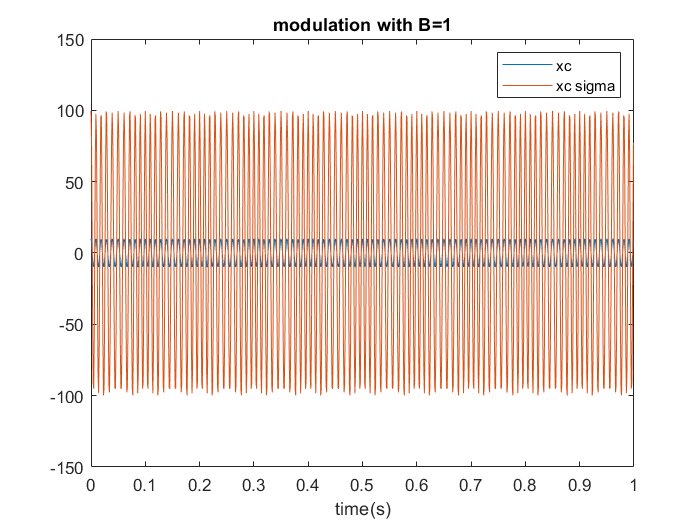


figure(2)
plot(t,xc2,t,double(xc2_sum_series))
legend('xc','xc sigma')
title('modulation with B=1')
xlabel('time(s)')
ylim([-150,150]);

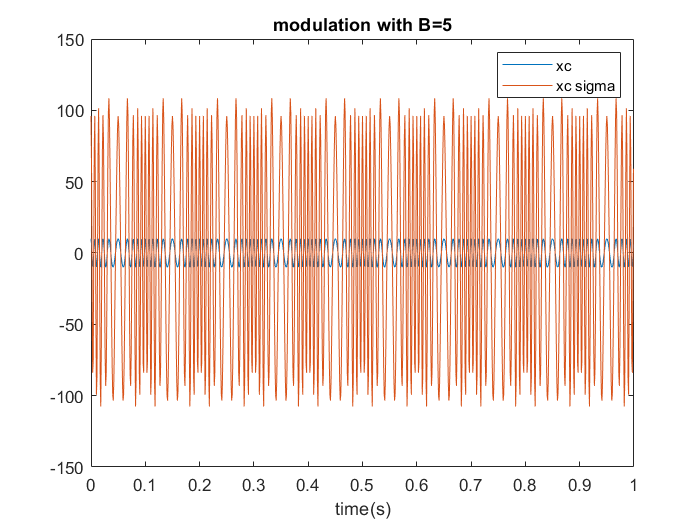


figure(3)
plot(t,xc3,t,double(xc3_sum_series))
legend('xc','xc sigma')
title('modulation with B=5')
xlabel('time(s)')
ylim([-150,150]);

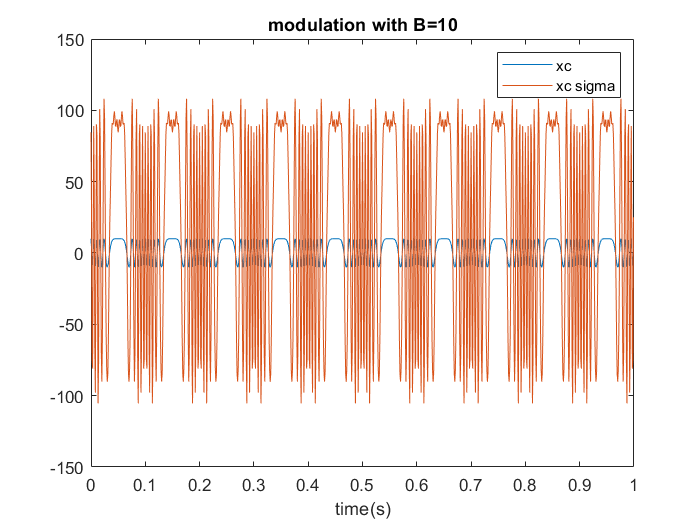


figure(4)
plot(t,xc4,t,double(xc4_sum_series))
legend('xc','xc sigma')
title('modulation with B=10')
xlabel('time(s)')
ylim([-150,150]);

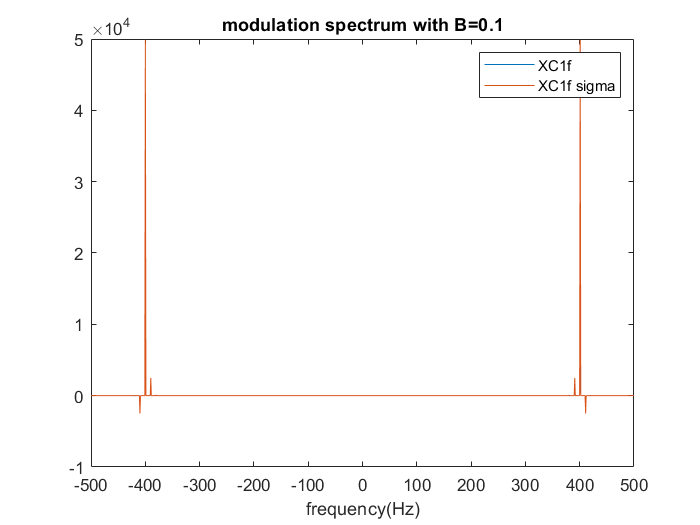


% spectrum

figure(5)
plot(f,real(XC1f),f,real(XC1_sum_f))
legend('XC1f','XC1f sigma')
title('modulation spectrum with B=0.1')
xlabel('frequency(Hz)')

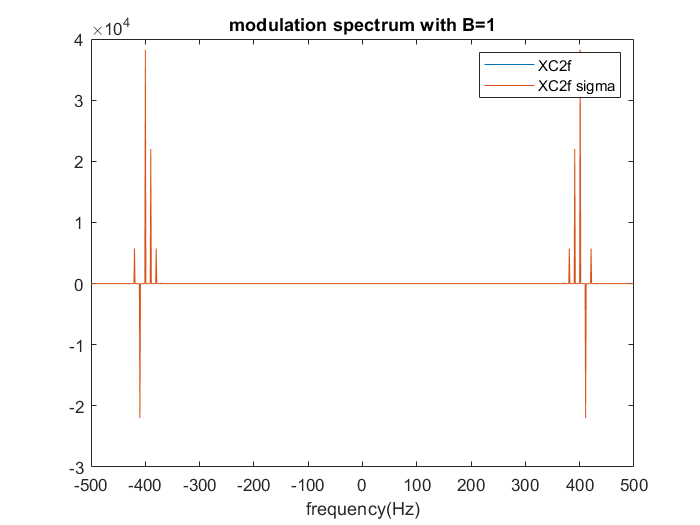


figure(6)
plot(f,real(XC2f),f,real(XC2_sum_f))
legend('XC2f','XC2f sigma')
title('modulation spectrum with B=1')
xlabel('frequency(Hz)')

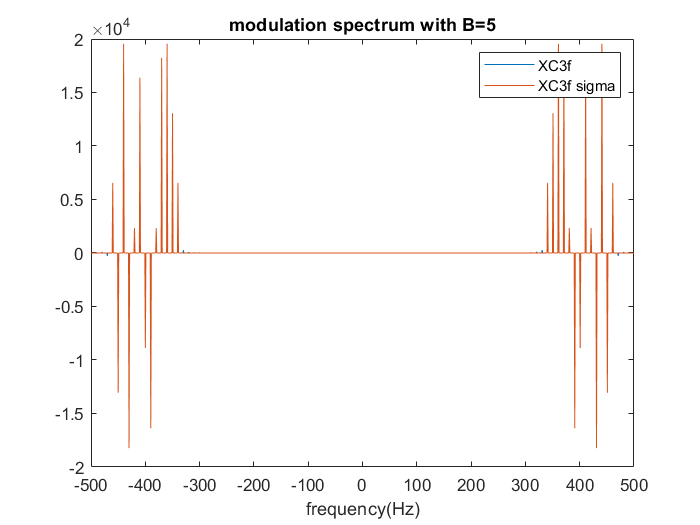


figure(7)
plot(f,real(XC3f),f,real(XC3_sum_f))
legend('XC3f','XC3f sigma')
title('modulation spectrum with B=5')
xlabel('frequency(Hz)')

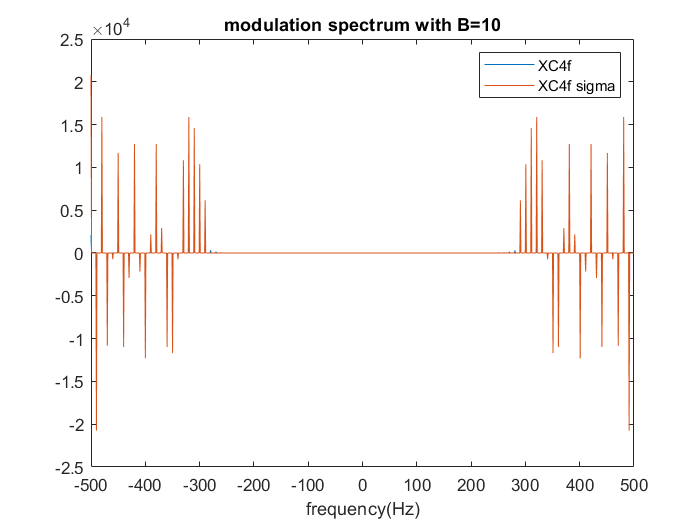


figure(8)
plot(f,real(XC4f),f,real(XC4_sum_f))
legend('XC4f','XC4f sigma')
title('modulation spectrum with B=10')
xlabel('frequency(Hz)')

clear all
clc
fs=10e03;
t=0:1/fs:0.2-1/fs;
x=sin(20*pi.*t);
x_new=trapz(t,x);
xcc=fmm(x,10,100,100,fs);   %fm using pm

xc =    10.0000    9.9801    9.9202    9.8195    9.6779    9.4952    9.2714    9.0067    8.7015    8.3566    7.9726    7.5508    7.0923    6.5987    6.0716    5.5131    4.9253    4.3106    3.6714    3.0107    2.3314    1.6366    0.9298    0.2142   -0.5063   -1.2281   -1.9472   -2.6598   -3.3617   -4.0490   -4.7176   -5.3633   -5.9822   -6.5701   -7.1232   -7.6378   -8.1101   -8.5367   -8.9143   -9.2399   -9.5106   -9.7240   -9.8778   -9.9703  -10.0000   -9.9657   -9.8667   -9.7029   -9.4743   -9.1816


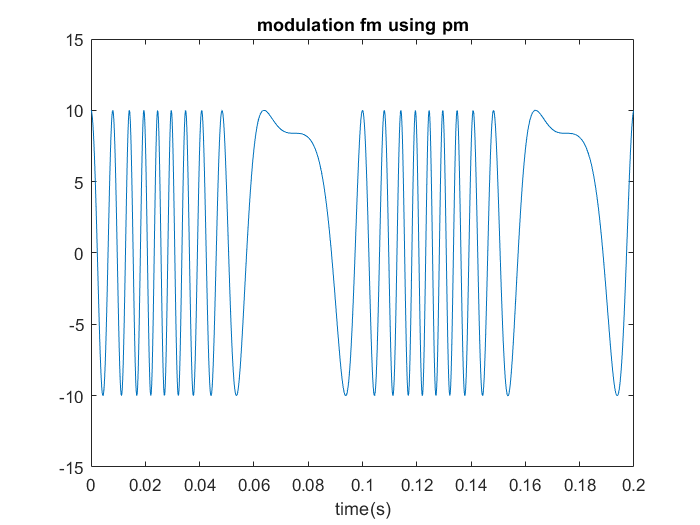

[xc_sample2,t_sample2]=pmm_tt(x,10,100,10,fs);   %pm

% modulation time vector

figure(1)                                   
plot(t_sample2,xcc)
title('modulation fm using pm')
xlabel('time(s)')
ylim([-15 15])

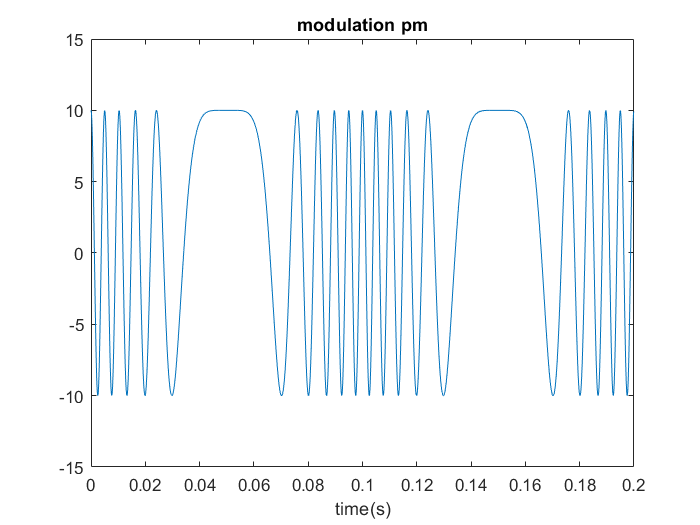


figure(2)                                   
plot(t_sample2,xc_sample2)
title('modulation pm')
xlabel('time(s)')
ylim([-15 15])